clearvars
close all

excelFile='displacements.xlsx'

excelFile = 'displacements.xlsx'

modelProblem = 'stress';

t = 1000.0; %N/mm^2
E = 10e+6;  %Young modulus (N/mm^2)
mu = 0.25;  %Poosson's ratio (dimensionless)
th=0.5;     %Thickness (mm)
forceLoad = [1000.0;0];   %(Fx, Fy) traction force

eval('CircleHolemesh01');

[numNod,ndim]=size(nodes);
numElem = size(elem,1);

numbering = 0;
plotElements(nodes, elem, numbering);

Select nodes on the left (fixed) and on the right (under traction).

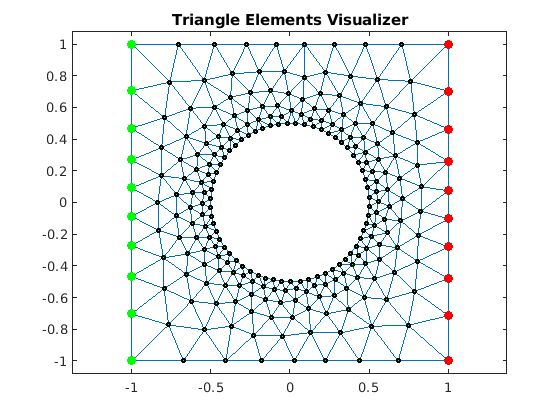

hold on
indLeft=find(nodes(:,1)< -0.99);
indRight= find(nodes(:,1) > 0.99);
plot(nodes(indLeft,1),nodes(indLeft,2),'o','MarkerFaceColor','green','MarkerEdgeColor','green')
plot(nodes(indRight,1),nodes(indRight,2),'o','MarkerFaceColor','red','MarkerEdgeColor','red')
hold off

Material properties

- modelProblem == 1: plane stress problem (thickness must be specified)

- modelProblem == 2: plane strain problem (thickness set to 1)

switch lower(modelProblem)
    case 'stress'
        c11=E/(1-mu^2);
        c22=c11;
        c12=mu*c11;
        c21=c12;
        c33=E/(2*(1+mu));   
    case 'strain'
        th=1;
        c11=E*(1-mu)/((1+mu)*(1-2*mu)); 
        c22=c11;
        c12=c11*mu/(1-mu);
        c21=c12;
        c33=E/(2*(1+mu));
    otherwise
        error('Please, specify whether it''s a ''stress'' or a ''strain'' problem!')
end
C = [c11, c12, 0; c21, c22, 0; 0, 0, c33];

K=zeros(numNod*ndim);
Q=zeros(numNod*ndim,1);
F=zeros(numNod*ndim,1);

for e=1:numElem
    %Ke=planeElastTriangStiffMatrixJR(nodes,elem,e,C,th); %<--- Do NOT use this!!!!
    Ke=planeElastTriangStiffMatrix(nodes,elem,e,C,th);
    rows=[
          ndim*elem(e,1)-1; ndim*elem(e,1); 
          ndim*elem(e,2)-1; ndim*elem(e,2);
          ndim*elem(e,3)-1; ndim*elem(e,3)
        ];
    cols = rows;
    K(rows,cols) = K(rows,cols) + Ke;
end


**Apply boundary conditions**

nodLoaded=indRight'; %List of nodes where the traction force is applied (transposed)
%Q=applyLoadsTriangJR(nodes,elem,nodLoaded,Q,forceLoad,1); %Use th instead???? DO NOT use this
Q=applyLoadsTriang(nodes,elem,nodLoaded,Q,forceLoad);

u=zeros(ndim*numNod,1);
fixedNodes = [ndim*indLeft-1; ndim*indLeft];
freeNodes= setdiff(1:ndim*numNod,fixedNodes);

u(fixedNodes) = 0;


**Reduced system**

Km=K(freeNodes,freeNodes);
Qm=Q(freeNodes);

%Solve the reduced system
um=Km\Qm;
u(freeNodes,1) = um;


**Post-process**

% Table with the displacements
format short e
displTable=table((1:numNod)',nodes(:,1),nodes(:,2),...
                  u(1:2:end),u(2:2:end),...
                  'VariableNames',{'NumNod','X','Y','UX','UY'});

%Save the table to an Excel file                      
writetable(displTable,excelFile);
%And show the displacements just for the last 10 nodes
displTable(end-9:end,:)

ans = 10×5 table
      NumNod          X              Y             UX            UY     
    __________    __________    ___________    __________    ___________

    2.5100e+02    8.2662e-01    -5.3671e-02    9.3031e-04    -5.7466e-06
    2.5200e+02    1.0000e+00     2.5850e-01    8.9109e-04     7.8482e-05
    2.5300e+02    1.0000e+00     4.6336e-01    7.8070e-04     1.0535e-04
    2.5400e+02    6.8197e-01    -1.0000e+00    4.3735e-04     6.6525e-05
    2.5500e+02    8.3100e-01     9.8970e-02    9.2239e-04     1.2574e-05
    2.5600e+02    1.0000e+00     7.3651e-02    9.4618e-04     2.5560e-05
    2.5700e+02    1.0000e+00     7.0241e-01    6.4869e-04     1.0372e-04
    2.5800e+02    1.0000e+00    -4.8001e-01    7.7225e-04    -1.0574e-04
    2.5900e+02    1.0000e+00    -1.0400e-01    9.3997e-04    -3.5284e-05
    2.600

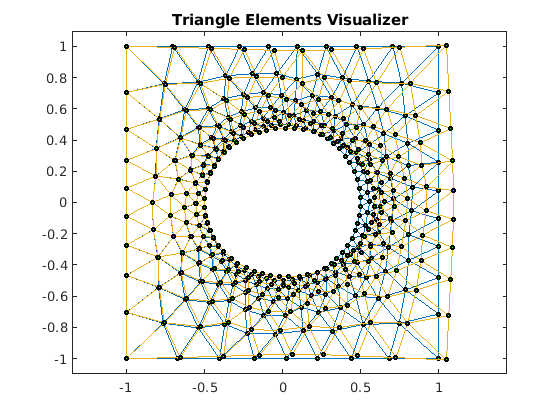



scale=100;
plotPlaneNodElemDespl(nodes, elem, u, scale);

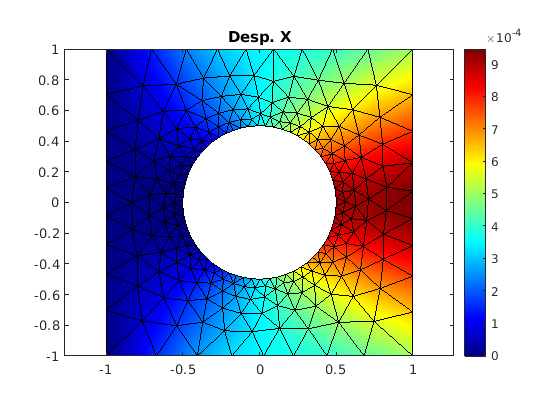

valueToShow=u(1:2:end,:);
titol='Desp. X';
colorTable='jet';
plotContourSolution(nodes,elem,valueToShow,titol,colorTable);

**Von Misses Stress**

**Remark:** for linear triangle elements the FEM method gives just a constant value of the stress tensor over each element

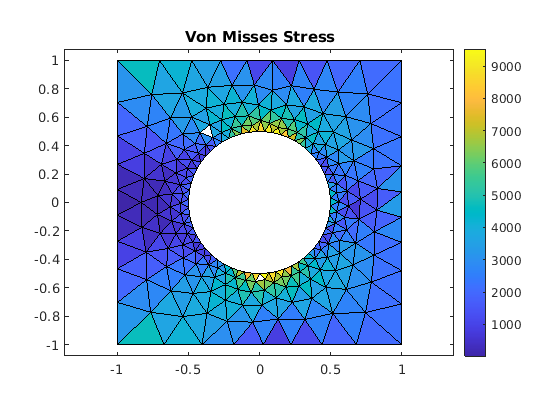

vonMisses=zeros(numElem,1);

for e=1:numElem
    nods = elem(e,:);
    rows = [
            ndim*nods(1)-1;ndim*nods(1); ...
            ndim*nods(2)-1;ndim*nods(2); ...
            ndim*nods(3)-1;ndim*nods(3)
            ];
    x = nodes(nods,1);
    y = nodes(nods,2);
    beta = [y(2)-y(3), y(3)-y(1), y(1)-y(2)];
    gamma = [x(3)-x(2), x(1)-x(3), x(2)-x(1)];
    Area2 = det([ones(3,1),x,y]);
    B = [
          beta(1),  0,        beta(2),  0,        beta(3),  0;
          0,        gamma(1), 0,        gamma(2), 0,        gamma(3);
          gamma(1), beta(1),  gamma(2), beta(2),  gamma(3), beta(3)
         ]/Area2;
    stress=C*B*u(rows,1);
    sigmaX=stress(1,1);
    sigmaY=stress(2,1);
    tauXY = stress(3,1);
    vonMisses(e,1)=sqrt(sigmaX^2+sigmaY^2-sigmaX*sigmaY+3*tauXY^2);
end

plotStressVM(nodes,elem,vonMisses)